# ECE588 Project Assignment 1

## 2-24-2022

## Winter 2022

Michael Bowyer

Kay Batt

Brandon Hagans

## Introduction

Please note that our group bought our own Turtlebot and connected to it rather than the simulation or Turtlebot from the lab.

Below is how we started ROS on the TurtleBot using SSH. Note that we used tmux in order to run multiple sessions in a single window. 

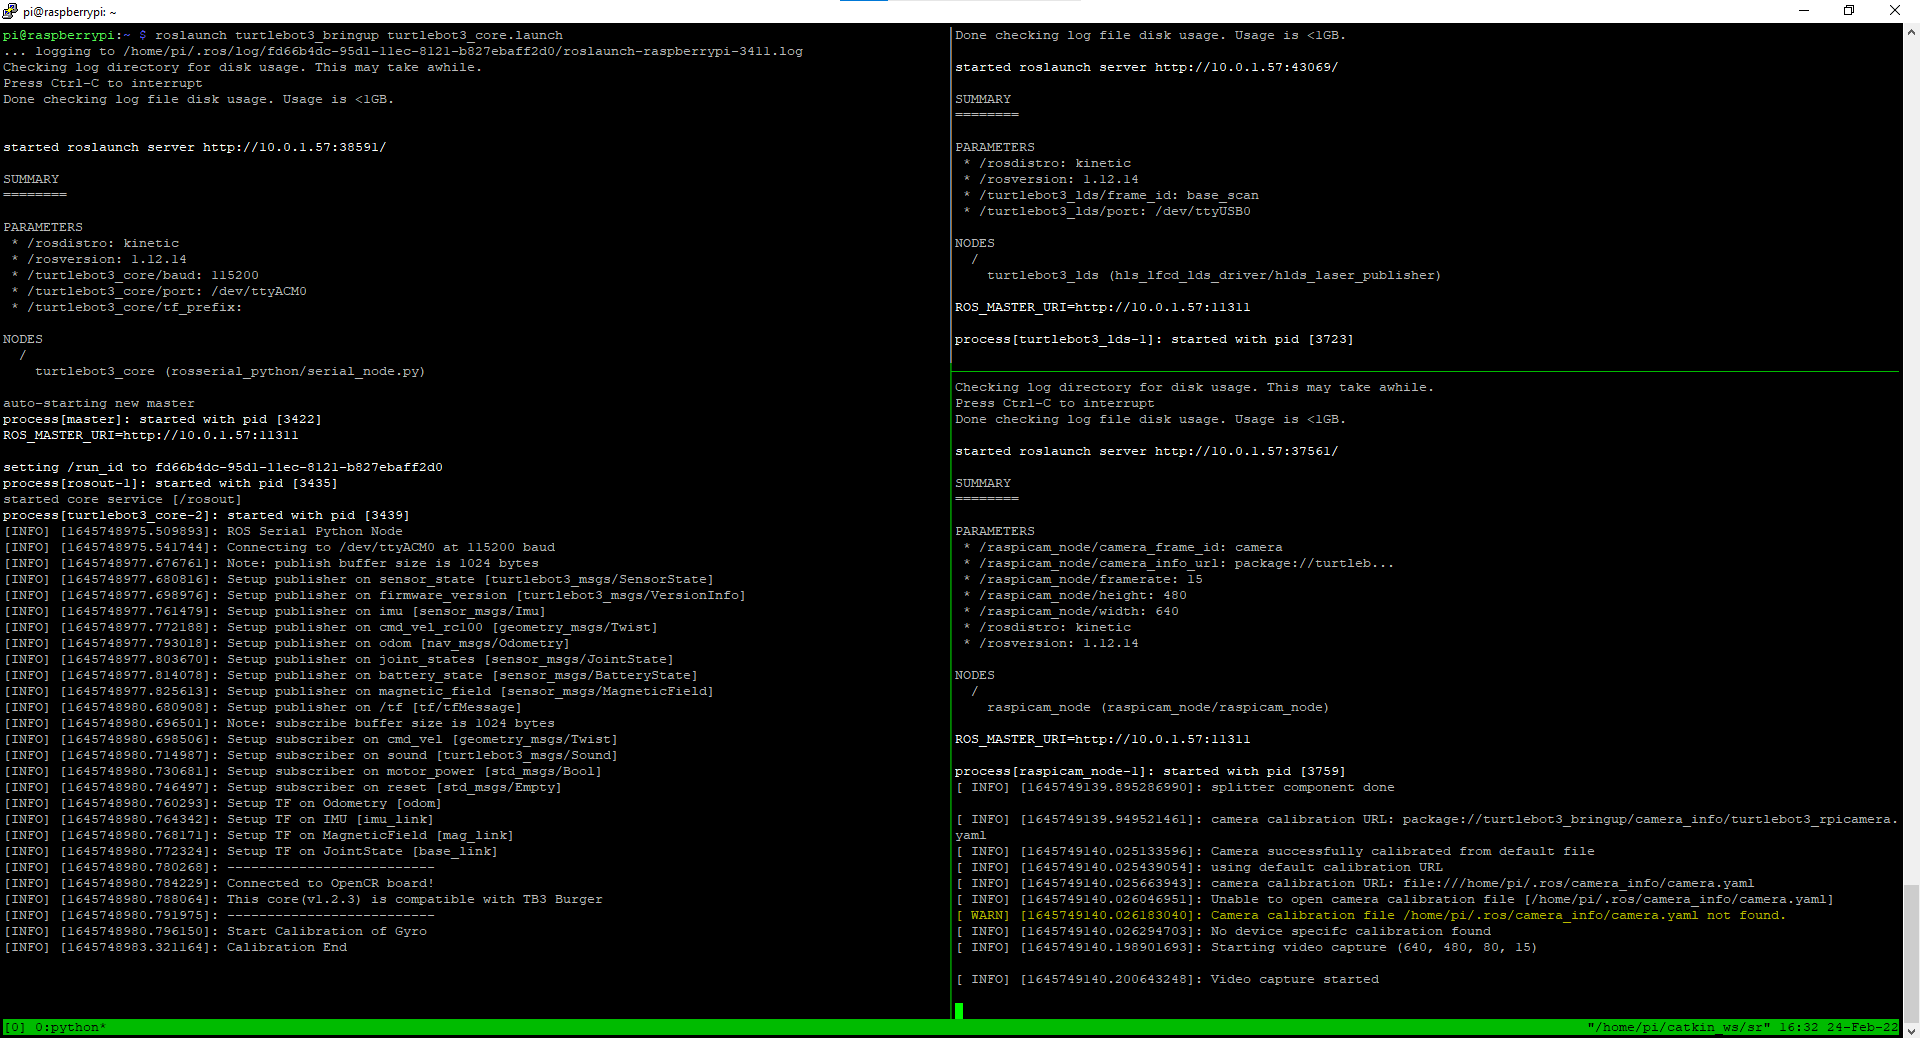

The following sections show how we pulled information on the various ROS topics.

## Connect to Turtle Bot

ip_TurtleBot = '10.0.1.57';    
ip_Matlab = '10.0.1.54';      

setenv('ROS_MASTER_URI', strcat('http://', ip_TurtleBot,':11311'))
setenv('ROS_IP', ip_Matlab)

rosinit(ip_TurtleBot)

The value of the ROS_IP environment variable, 10.0.1.54, will be used to set the advertised address for the ROS node.
Initializing global node /matlab_global_node_67359 with NodeURI http://10.0.1.54:57211/


ans = datetime
   24-Feb-2022 19:25:07


## Echoing Ros Topics

datetime

ans = datetime
   24-Feb-2022 19:25:07


### /cmd_vel

rostopic info /cmd_vel

Type: geometry_msgs/Twist
 
Publishers:
 
Subscribers:
* /turtlebot3_core (http://10.0.1.57:45775/)


%msg_vel = rostopic("echo", "/cmd_vel")

Since there are no publishers for the velocity, there is no message content to display. This is why the line 'msg_vel = rostopic("echo", "/cmd_vel")' is commented, since it will run forever waiting for data.

### /scan

rostopic info /scan

Type: sensor_msgs/LaserScan
 
Publishers:
* /turtlebot3_lds (http://10.0.1.57:42047/)
 
Subscribers:
* /matlab_global_node_22226 (http://10.0.1.57:50091/)


msg_scan = rostopic("echo", "/scan")

msg_scan =   ROS LaserScan message with properties:

       MessageType: 'sensor_msgs/LaserScan'
            Header: [1×1 Header]
          AngleMin: 0
          AngleMax: 6.2657
    AngleIncrement: 0.0175
     TimeIncrement: 2.9900e-05
          ScanTime: 0
          RangeMin: 0.1200
          RangeMax: 3.5000
            Ranges: [360×1 single]
       Intensities: [360×1 single]

  Use showdetails to show the contents of the message


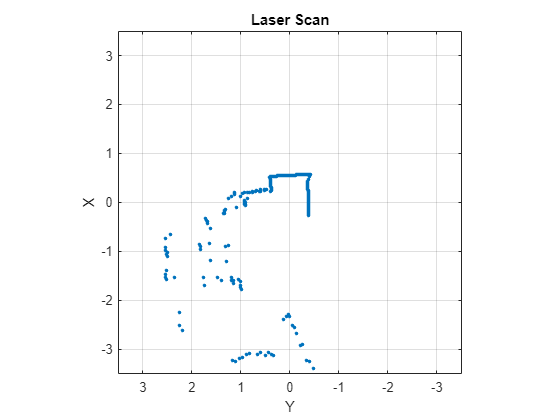

laser_sub = rossubscriber('/scan');
scan_data = receive(laser_sub);
plot(scan_data);

### /raspicam_node/image/compressed

rostopic info /raspicam_node/image/compressed

Type: sensor_msgs/CompressedImage
 
Publishers:
* /raspicam_node (http://10.0.1.57:43265/)
 
Subscribers:


msg_camera = rostopic("echo", "/raspicam_node/image/compressed")

msg_camera =   ROS CompressedImage message with properties:

    MessageType: 'sensor_msgs/CompressedImage'
         Header: [1×1 Header]
         Format: 'jpg'
           Data: [103770×1 uint8]

  Use showdetails to show the contents of the message


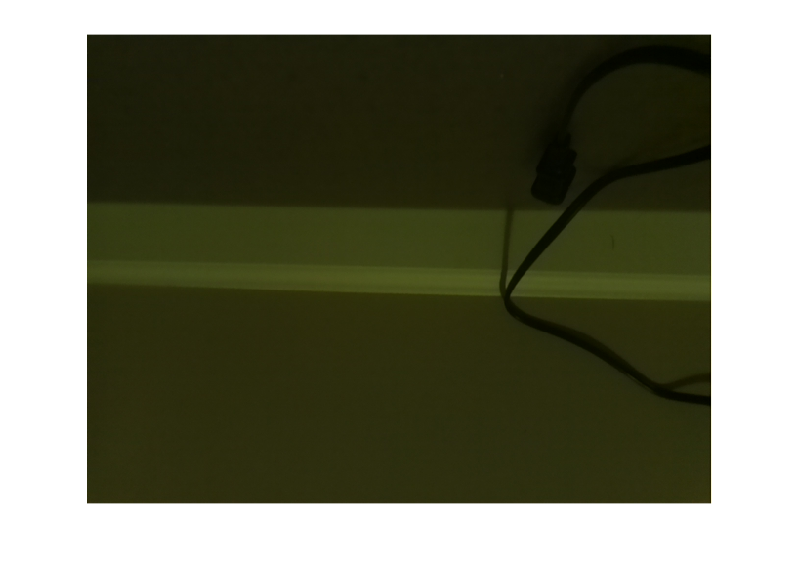

TurtleBot_Topic.picam = '/raspicam_node/image/compressed';
image_sub = rossubscriber(TurtleBot_Topic.picam);
image_compressed = receive(image_sub);

image_compressed.Format = 'bgr8; jpeg compressed bgr8';
figure
imshow(readImage(image_compressed))

### /imu

rostopic info /imu

Type: sensor_msgs/Imu
 
Publishers:
* /turtlebot3_core (http://10.0.1.57:45775/)
 
Subscribers:


msg_imu = rostopic("echo", "/imu")

msg_imu =   ROS Imu message with properties:

                     MessageType: 'sensor_msgs/Imu'
                          Header: [1×1 Header]
                     Orientation: [1×1 Quaternion]
                 AngularVelocity: [1×1 Vector3]
              LinearAcceleration: [1×1 Vector3]
           OrientationCovariance: [9×1 double]
       AngularVelocityCovariance: [9×1 double]
    LinearAccelerationCovariance: [9×1 double]

  Use showdetails to show the contents of the message


msg_imu.AngularVelocity

ans =   ROS Vector3 message with properties:

    MessageType: 'geometry_msgs/Vector3'
              X: 0
              Y: 0
              Z: 0

  Use showdetails to show the contents of the message


msg_imu.LinearAcceleration

ans =   ROS Vector3 message with properties:

    MessageType: 'geometry_msgs/Vector3'
              X: 0.1598
              Y: -0.0646
              Z: 9.9455

  Use showdetails to show the contents of the message


### /odom

rostopic info /odom

Type: nav_msgs/Odometry
 
Publishers:
* /turtlebot3_core (http://10.0.1.57:45775/)
 
Subscribers:


msg_odom = rostopic("echo", "/odom")

msg_odom =   ROS Odometry message with properties:

     MessageType: 'nav_msgs/Odometry'
          Header: [1×1 Header]
            Pose: [1×1 PoseWithCovariance]
           Twist: [1×1 TwistWithCovariance]
    ChildFrameId: 'base_footprint'

  Use showdetails to show the contents of the message


msg_odom.Pose.Pose.Position

ans =   ROS Point message with properties:

    MessageType: 'geometry_msgs/Point'
              X: 1.3375e-11
              Y: 3.2724e-09
              Z: 0

  Use showdetails to show the contents of the message


msg_odom.Pose.Pose.Position

ans =   ROS Point message with properties:

    MessageType: 'geometry_msgs/Point'
              X: 1.3375e-11
              Y: 3.2724e-09
              Z: 0

  Use showdetails to show the contents of the message
